**Business case 4 - Investment Replica**

clear all
close all

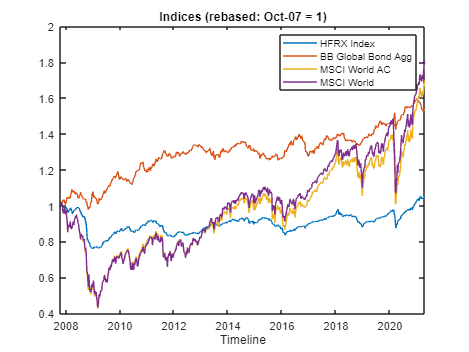


figure
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

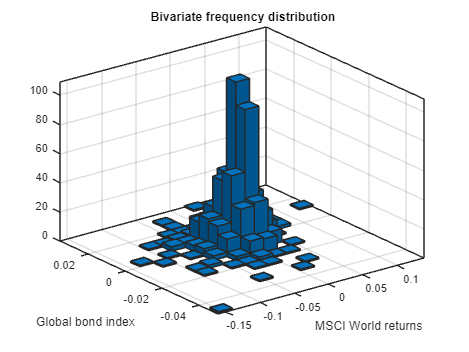

figure
histogram2(price2ret(MXWO),price2ret(LEGATRUU))
xlabel('MSCI World returns')
ylabel('Global bond index')
title('Bivariate frequency distribution')

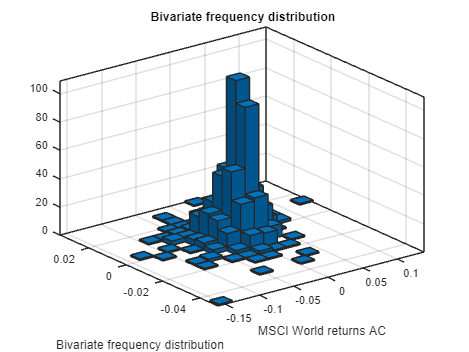


figure
histogram2(price2ret(MXWO),price2ret(LEGATRUU))
xlabel('MSCI World returns AC')
ylabel('Bivariate frequency distribution')
title('Bivariate frequency distribution')

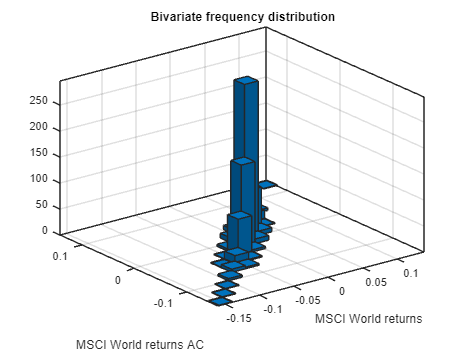


figure
histogram2(price2ret(MXWO),price2ret(MXWD))
xlabel('MSCI World returns')
ylabel('MSCI World returns AC')
title('Bivariate frequency distribution')

Sottolineare correlazione tra gli MSCI

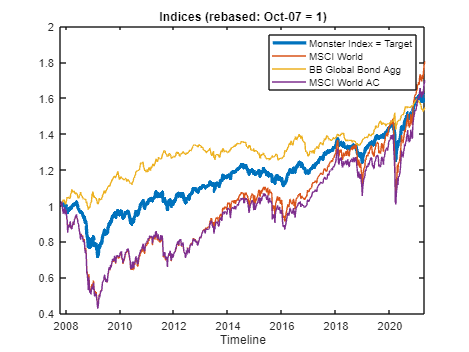

% Synthetic target weights
wMXWO = 0.2; 
wMXWD = 0.2;
wLEGATRUU = 0.6;
%Primi due simili

% Building the target
y = wMXWD*price2ret(MXWD) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

figure
p = plot(XTab.Date,target,'DisplayName','Monster Index = Target');
p.LineWidth = 3;
hold on;
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

Commento confronto andamento singoli indici e monster. 

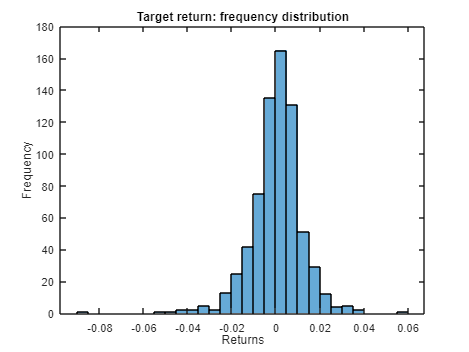

figure
histogram(y)
title('Target return: frequency distribution')
ylabel('Frequency')
xlabel('Returns')

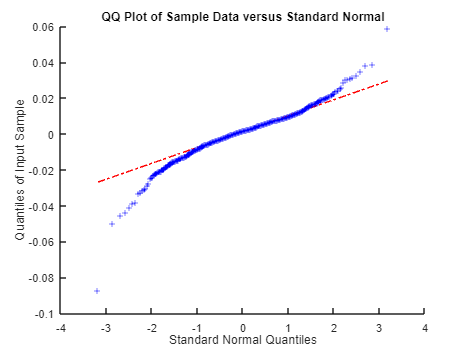


figure
qqplot(y)

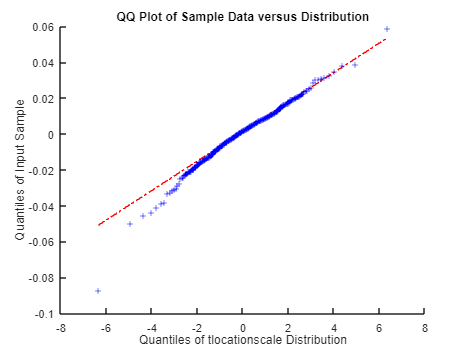


figure
qqplot(y, makedist("tLocationScale"))

Vogliamo replicare coi futures

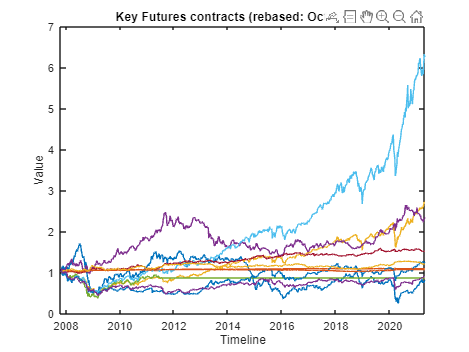

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(XTab.Date, ret2price(X))
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')

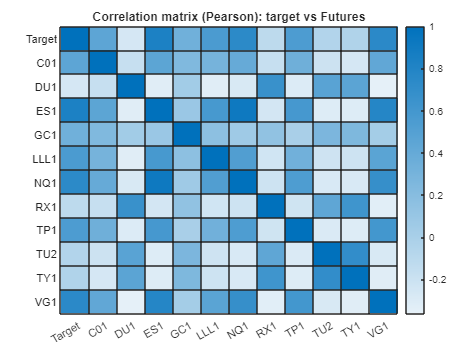

figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Pearson'));
h.Title = 'Correlation matrix (Pearson): target vs Futures';

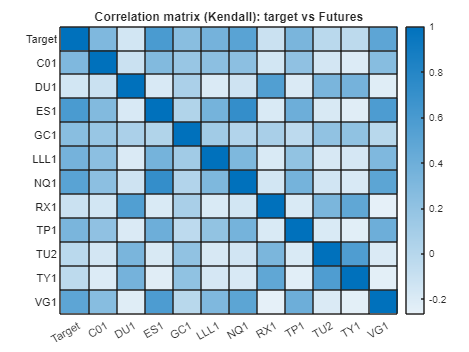


figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Kendall'));
h.Title = 'Correlation matrix (Kendall): target vs Futures';

Si può fare: RSI e Median

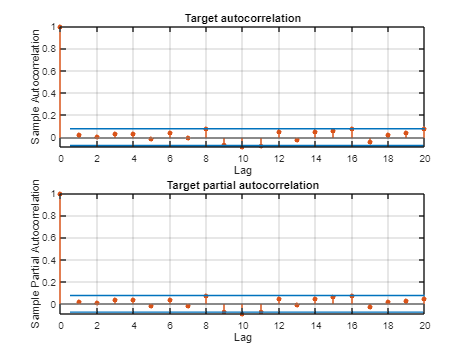

figure
subplot(2,1,1)
autocorr(y)
title('Target autocorrelation')
subplot(2,1,2)
parcorr(y)
title('Target partial autocorrelation')

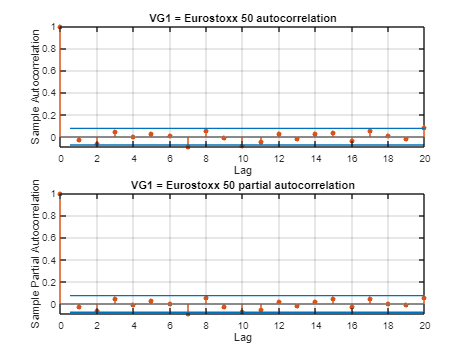

figure
subplot(2,1,1)
autocorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 autocorrelation')
subplot(2,1,2)
parcorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 partial autocorrelation')

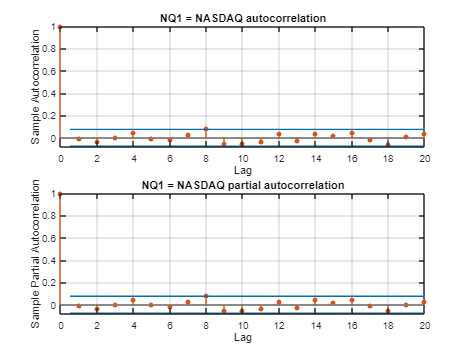

figure
subplot(2,1,1)
autocorr(price2ret(NQ1))
title('NQ1 = NASDAQ autocorrelation')
subplot(2,1,2)
parcorr(price2ret(NQ1))
title('NQ1 = NASDAQ partial autocorrelation')

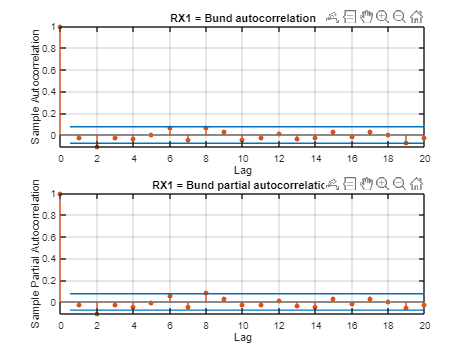

figure
subplot(2,1,1)
autocorr(price2ret(RX1))
title('RX1 = Bund autocorrelation')
subplot(2,1,2)
parcorr(price2ret(RX1))
title('RX1 = Bund partial autocorrelation')

rollingWindow = 156; % in weeks (52 = 1Y, 104 = 2Y...)
%Si possono fare confronti cambiando la rolling window e alpha e
%confrontando con un algoritmo ad alpha mobile

%rw 104 156 208 260 + alpha 0.05 0.5 0.95

i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
    [b,fitinfo] = lasso(X(startSample:endSample,:),y(startSample:endSample),'Alpha',0.85,'CV',5, 'Intercept',false);
%   lam = fitinfo.IndexMinMSE; % lambda corresponding to MinMSE (better fit)
%   lam = fitinfo.Index1SE; % lambda 1SE away from MinMSE (more robust)
    lam = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2); % lambda half-way between MinMSE and 1SE away from MinMSE
    b = b(:,lam);
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b'];
    r = X(endSample + 1,:)*b;
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again

**Financial statistics**

TEV -> Per confronto 

TE = rENet2 - y(rollingWindow + 1: end); % tracking error
TEV = std(TE)*sqrt(52)

Gross

In generale, un buon risultato in un portafoglio di replica dovrebbe essere caratterizzato da un ER positivo, una volatilità limitata e una bassa correlazione con il benchmark di riferimento. Un portafoglio che ottiene un ER positivo ma con una volatilità elevata potrebbe essere più rischioso di quanto sia accettabile, mentre un portafoglio con un ER negativo ma una bassa volatilità potrebbe essere considerato accettabile se offre una buona protezione dal rischio.

logRClone = diff(log(ret2price(rENet2))); % ...much easier to compute annualized metrics from log-returns
logRTarget = diff(log(ret2price(y(rollingWindow + 1: end))));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1

meanTRTarget =    0.046170834804194


meanTRClone = exp(mean(logRClone)*52) - 1

meanTRClone =    0.046232246630127


meanER = exp(mean(logTE)*52) - 1

meanER =      5.870152740805601e-05


Quando l'ER del portafoglio di replica è più alto del target, significa che il portafoglio di replica ha generato un rendimento superiore rispetto all'indice di riferimento, ovvero il portafoglio target. In altre parole, il portafoglio di replica ha aggiunto valore rispetto all'indice di riferimento.

Ci possono essere diverse ragioni per cui ciò accade. Ad esempio, il gestore del portafoglio di replica potrebbe aver selezionato titoli o strategie di investimento che hanno reso meglio rispetto a quelli del portafoglio target. 

Tuttavia, è importante valutare anche altri fattori oltre all'ER per determinare se il risultato del portafoglio di replica è effettivamente positivo. Ad esempio, è importante considerare la volatilità del portafoglio, la diversificazione e il rischio complessivo del portafoglio.

IR

IR = meanER/TEV

IR =    0.001771528461561


Turnover

Turnover = calcTurnover(bENet2); % weekly turnover
meanTurnover = mean(Turnover)*52 % average annual turnover

meanTurnover =   12.028429069201691


tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
meanTradingCosts = meanTurnover*tradingCosts

meanTradingCosts =    0.004811371627681



NetTR = meanTRClone - meanTradingCosts % transaction costs (hp: buyCosts=sellCost)

NetTR =    0.041420875002446


NetER = meanER - meanTradingCosts

NetER =   -0.004752670100273


NetIR = NetER/TEV

NetIR =   -0.143428812209872


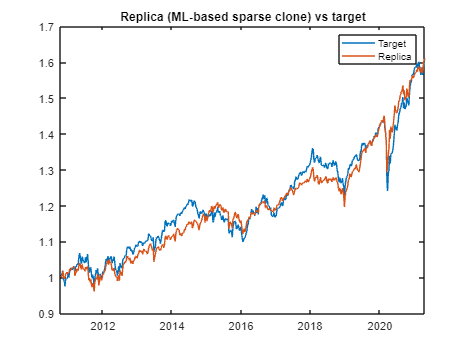

figure
plot(Date(rollingWindow+1:end),ret2price(y(rollingWindow + 1: end)),'DisplayName','Target');
hold on;
plot(Date(rollingWindow+1:end),ret2price(rENet2),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

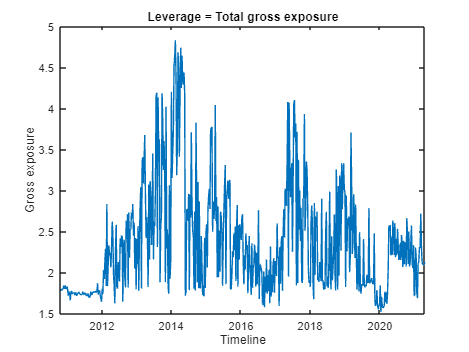

figure
plot(Date(rollingWindow+2:end),GrossExposure+1); % add 1 for your collateral + margins
title('Leverage = Total gross exposure')
xlabel('Timeline')
ylabel('Gross exposure')
hold off;